clc; clear; close all;

%% Alunos: Felipe Ferrer Sorrilha e Guilherme Pança Franco

%% Configurações
arq_normal = 'N09_M07_F10_K001_1.mat';
arq_falha  = 'N09_M07_F10_KA04_1.mat';
fs = 64000;

%% Carregar arquivos
D = load(arq_normal); 
fn = fieldnames(D);
struct_normal = D.(fn{1});
sinal_normal = double(struct_normal.Y(1).Data(:));

D = load(arq_falha); 
fn = fieldnames(D);
struct_falha = D.(fn{1});
sinal_falha = double(struct_falha.Y(1).Data(:));

% Igualar tamanhos
Lmin = min(length(sinal_normal), length(sinal_falha));
sinal_normal = sinal_normal(1:Lmin); 
sinal_falha = sinal_falha(1:Lmin);

%% Pré-processamento
sinal_normal = detrend(sinal_normal, 'constant');
sinal_falha  = detrend(sinal_falha, 'constant');

fc = 2000; % Corte 2 kHz
[b,a] = butter(6, fc/(fs/2), 'low');
s_norm_f = filtfilt(b,a,sinal_normal);
s_falha_f = filtfilt(b,a,sinal_falha);

%% Estimativa espectral com Welch
nfft = 2^nextpow2(65536);
window = hamming(8192);
noverlap = round(0.5*length(window));

[psd_norm, f] = pwelch(s_norm_f, window, noverlap, nfft, fs);
[psd_falha, f] = pwelch(s_falha_f, window, noverlap, nfft, fs);

%% Plot: zoom na fundamental 
figure('Color','w','Position',[100 100 1000 700]);

subplot(3,2,1);
plot(f,10*log10(psd_norm),'b'); hold on;
plot(f,10*log10(psd_falha),'r--'); 
xlim([40 80]); grid on;
title('MCSA (PSD, zoom 40-80 Hz)'); 
xlabel('Frequência (Hz)'); ylabel('PSD (dB/Hz)');
legend('Normal','Falha');

%% Envelope pelo Hilbert
env_norm = abs(hilbert(s_norm_f));
env_falha = abs(hilbert(s_falha_f));

fc_env = 100; 
[be, ae] = butter(4, fc_env/(fs/2), 'low');
env_norm_f = filtfilt(be, ae, env_norm);
env_falha_f = filtfilt(be, ae, env_falha);

[psd_env_n, fenv] = pwelch(env_norm_f, window, noverlap, nfft, fs);
[psd_env_f, fenv] = pwelch(env_falha_f, window, noverlap, nfft, fs);

subplot(3,2,2);
plot(fenv, 10*log10(psd_env_n), 'b'); hold on;
plot(fenv, 10*log10(psd_env_f), 'r'); 
xlim([0 100]); grid on;
title('Espectro do Envelope (PSD)'); 
xlabel('Freq (Hz)'); ylabel('PSD (dB/Hz)');
legend('Envelope Normal','Envelope Falha');

%% Métricas básicas
fprintf('========================================\n');


% RMSE entre espectros (de um jeito simples que achamos na net)
rmse_psd = sqrt(mean((psd_norm - psd_falha).^2));
fprintf('1. RMSE entre espectros PSD: %.6e\n', rmse_psd);

1. RMSE entre espectros PSD: 5.513342e+00


% RMSE = 5.513342

% Energia na faixa 0-100 Hz do envelope
idx_env = fenv <= 100;
if sum(idx_env) > 0
    energia_env_norm = sum(psd_env_n(idx_env));
    energia_env_falha = sum(psd_env_f(idx_env));
    if energia_env_norm > 0
        aumento_env = (energia_env_falha - energia_env_norm)/energia_env_norm*100;
        fprintf('2. Aumento energia envelope 0-100Hz: %.2f%%\n', aumento_env);
    else
        aumento_env = 0;
        fprintf('2. Energia do envelope normal muito baixa\n');
    end
else
    aumento_env = 0;
    fprintf('2. Faixa do envelope não disponível\n');
end

2. Aumento energia envelope 0-100Hz: -70.26%



%% Detecção de picos 40-80Hz
froi = f>=40 & f<=80;
if sum(froi) > 0
    [PksN, locsN] = findpeaks(psd_norm(froi), f(froi), 'MinPeakProminence', max(psd_norm(froi))/50);
    [PksF, locsF] = findpeaks(psd_falha(froi), f(froi), 'MinPeakProminence', max(psd_falha(froi))/50);
    
    subplot(3,2,3);
    plot(f(froi), 10*log10(psd_norm(froi)),'b'); hold on;
    plot(f(froi), 10*log10(psd_falha(froi)),'r--');
    plot(locsN, 10*log10(PksN), 'bo'); 
    plot(locsF, 10*log10(PksF), 'r^');
    xlim([40 80]); grid on;
    title('Picos 40-80Hz'); 
    xlabel('Hz'); ylabel('PSD (dB/Hz)');
    legend('Normal','Falha','Picos Normal','Picos Falha');
    
    fprintf('3. Pico principal normal: %.1f Hz\n', locsN(1));
    fprintf('   Pico principal falha: %.1f Hz\n', locsF(1));
else
    fprintf('3. Faixa 40-80Hz não disponível\n');
end

3. Pico principal normal: 57.6 Hz


   Pico principal falha: 42.0 Hz



%% Análise de Frequências de Falha
fprintf('\n--- FREQUÊNCIAS CARACTERÍSTICAS ---\n');


--- FREQUÊNCIAS CARACTERÍSTICAS ---



% Valores típicos para motor de indução
f_s = 60;              % Frequência da rede (Hz)
rpm = 1500;            
fr = rpm/60;           % Frequência rotacional (Hz)

% Frequência BPFO simplificada (aproximação comum)
BPFO = 3.1 * fr;  
fprintf('Frequência da rede (f_s): %.0f Hz\n', f_s);

Frequência da rede (f_s): 60 Hz


fprintf('Frequência rotacional (f_r): %.2f Hz\n', fr);

Frequência rotacional (f_r): 25.00 Hz


fprintf('BPFO (falha anel externo): %.2f Hz\n', BPFO);

BPFO (falha anel externo): 77.50 Hz


fprintf('Bandas laterais esperadas:\n');

Bandas laterais esperadas:


fprintf('  60 - BPFO = %.2f Hz\n', f_s - BPFO);

  60 - BPFO = -17.50 Hz


fprintf('  60 + BPFO = %.2f Hz\n', f_s + BPFO);

  60 + BPFO = 137.50 Hz



%% Análise de Bandas Laterais
subplot(3,2,4);
plot(f, 10*log10(psd_falha), 'r', 'LineWidth', 1); hold on;
xline(f_s, 'k--', 'LineWidth', 1.5);
xline(f_s - BPFO, 'g--', 'LineWidth', 1.5);
xline(f_s + BPFO, 'g--', 'LineWidth', 1.5);
xlim([f_s-20, f_s+20]); grid on;
title('Bandas Laterais - Falha Anel Externo');
xlabel('Frequência (Hz)'); ylabel('PSD (dB/Hz)');
legend('Falha','60 Hz','60 - BPFO','60 + BPFO');

% Verificar presença de bandas laterais
tolerancia = 2;
f_banda_inf = f_s - BPFO;
f_banda_sup = f_s + BPFO;

% Buscar bandas laterais
banda_inf_detectada = false;
banda_sup_detectada = false;

if f_banda_inf > 0 && f_banda_inf < max(f)
    idx_inf = find(f >= f_banda_inf-tolerancia & f <= f_banda_inf+tolerancia);
    if ~isempty(idx_inf)
        [pk_inf, ~] = max(psd_falha(idx_inf));
        fprintf('\n✓ Banda lateral inferior detectada em %.1f Hz\n', f_banda_inf);
        banda_inf_detectada = true;
    end
end

if f_banda_sup > 0 && f_banda_sup < max(f)
    idx_sup = find(f >= f_banda_sup-tolerancia & f <= f_banda_sup+tolerancia);
    if ~isempty(idx_sup)
        [pk_sup, ~] = max(psd_falha(idx_sup));
        fprintf('✓ Banda lateral superior detectada em %.1f Hz\n', f_banda_sup);
        banda_sup_detectada = true;
    end
end

✓ Banda lateral superior detectada em 137.5 Hz



%% Reconstrução pro bandas simplificada (via FFT)
fprintf('\n--- RECONSTRUÇÃO POR BANDAS ---\n');


--- RECONSTRUÇÃO POR BANDAS ---



% Método via FFT
N = length(s_falha_f);
freqs = (0:N-1)*(fs/N);

% Calcular FFT do sinal com falha
S_falha = fft(s_falha_f);

% 1. Banda da fundamental (55-65 Hz)
mask1 = (freqs >= 55 & freqs <= 65) | (freqs >= fs-65 & freqs <= fs-55);
S_banda1 = S_falha .* mask1';
s_banda1 = real(ifft(S_banda1));

% 2. Bandas laterais (se detectadas)
s_banda2 = zeros(size(s_falha_f));
s_banda3 = zeros(size(s_falha_f));

if banda_inf_detectada
    mask2 = (freqs >= f_banda_inf-1 & freqs <= f_banda_inf+1) | ...
            (freqs >= fs-f_banda_inf-1 & freqs <= fs-f_banda_inf+1);
    S_banda2 = S_falha .* mask2';
    s_banda2 = real(ifft(S_banda2));
end

if banda_sup_detectada
    mask3 = (freqs >= f_banda_sup-1 & freqs <= f_banda_sup+1) | ...
            (freqs >= fs-f_banda_sup-1 & freqs <= fs-f_banda_sup+1);
    S_banda3 = S_falha .* mask3';
    s_banda3 = real(ifft(S_banda3));
end

% Sinal reconstruído
s_reconstruido = s_banda1 + s_banda2 + s_banda3;

% Calcular RMSE de forma SEGURA
% Primeiro, verificar se os sinais não são todos zeros
% Normalizar ambos os sinais
s_falha_norm = s_falha_f / max(abs(s_falha_f));
s_reconst_norm = s_reconstruido / max(abs(s_reconstruido));
    
% Calcular RMSE
diferenca = s_falha_norm - s_reconst_norm;
rmse_reconst = sqrt(mean(diferenca.^2));
    
% Calcular fator de similaridade (0-100%)
similaridade = (1 - rmse_reconst) * 100;
    
fprintf('RMSE reconstrução: %.4f\n', rmse_reconst);

RMSE reconstrução: 0.6212


fprintf('Similaridade sinal original-reconstruído: %.1f%%\n', similaridade);

Similaridade sinal original-reconstruído: 37.9%


    
% Plot do sinal reconstruído
subplot(3,2,5);
t = (0:min(2000,length(s_falha_norm))-1)/fs;
plot(t, s_falha_norm(1:length(t)), 'b', 'LineWidth', 1); 
hold on;
plot(t, s_reconst_norm(1:length(t)), 'r--', 'LineWidth', 1.5);
xlabel('Tempo (s)'); ylabel('Amplitude (normalizada)');
title('Original vs Reconstruído (normalizados)');
legend('Original', 'Reconstruído');
grid on;
    


%% ANÁLISE DE ENERGIA
fprintf('\n--- ANÁLISE DE ENERGIA POR FAIXA ---\n');


--- ANÁLISE DE ENERGIA POR FAIXA ---



% 1. Energia na fundamental (58-62 Hz)
idx_fund = f >= 58 & f <= 62;
if sum(idx_fund) > 0
    E_fund_norm = sum(psd_norm(idx_fund));
    E_fund_falha = sum(psd_falha(idx_fund));
    if E_fund_norm > 0
        variacao_fund = (E_fund_falha - E_fund_norm)/E_fund_norm*100;
        fprintf('Fundamental (58-62 Hz):\n');
        fprintf('  Normal: %.3e, Falha: %.3e\n', E_fund_norm, E_fund_falha);
        fprintf('  Variação: %.2f%%\n', variacao_fund);
    end
end

Fundamental (58-62 Hz):


  Normal: 3.644e-02, Falha: 3.783e-02


  Variação: 3.81%



% 2. Energia no envelope
idx_env_lf = fenv <= 20;
idx_env_mf = fenv > 20 & fenv <= 100;

if sum(idx_env_lf) > 0
    E_env_lf_norm = sum(psd_env_n(idx_env_lf));
    E_env_lf_falha = sum(psd_env_f(idx_env_lf));
    if E_env_lf_norm > 0
        variacao_lf = (E_env_lf_falha - E_env_lf_norm)/E_env_lf_norm*100;
        fprintf('\nEnvelope LF (0-20 Hz):\n');
        fprintf('  Normal: %.3e, Falha: %.3e\n', E_env_lf_norm, E_env_lf_falha);
        fprintf('  Variação: %.2f%%\n', variacao_lf);
    end
end


Envelope LF (0-20 Hz):


  Normal: 9.499e+03, Falha: 2.824e+03


  Variação: -70.27%



if sum(idx_env_mf) > 0
    E_env_mf_norm = sum(psd_env_n(idx_env_mf));
    E_env_mf_falha = sum(psd_env_f(idx_env_mf));
    if E_env_mf_norm > 0
        variacao_mf = (E_env_mf_falha - E_env_mf_norm)/E_env_mf_norm*100;
        fprintf('Envelope MF (20-100 Hz):\n');
        fprintf('  Normal: %.3e, Falha: %.3e\n', E_env_mf_norm, E_env_mf_falha);
        fprintf('  Variação: %.2f%%\n', variacao_mf);
    end
end

Envelope MF (20-100 Hz):


  Normal: 4.081e+00, Falha: 1.527e+00


  Variação: -62.59%


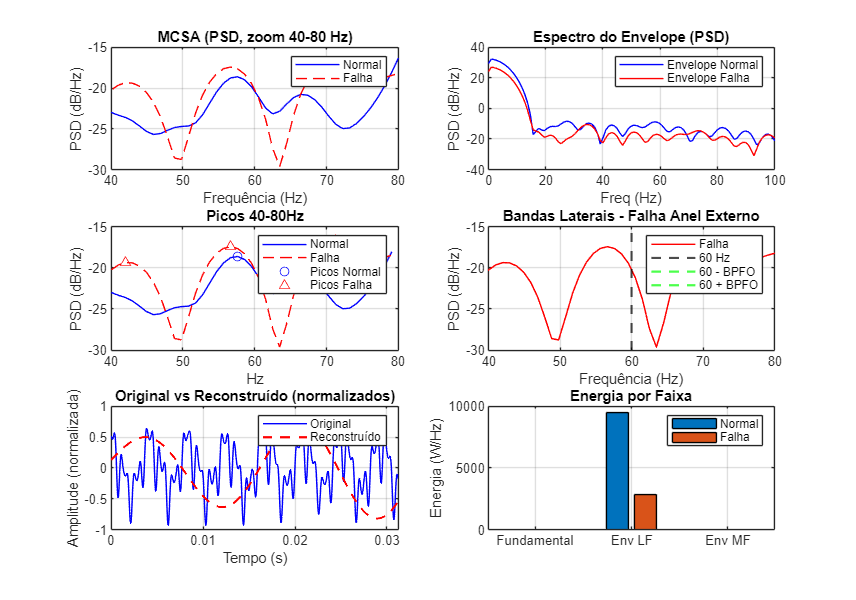


%% GRÁFICO DE ENERGIA
subplot(3,2,6);

% Preparar dados para gráfico
faixas = {};
energias_norm = [];
energias_falha = [];

if sum(idx_fund) > 0 && E_fund_norm > 0
    faixas{end+1} = 'Fundamental';
    energias_norm(end+1) = E_fund_norm;
    energias_falha(end+1) = E_fund_falha;
end

if sum(idx_env_lf) > 0 && E_env_lf_norm > 0
    faixas{end+1} = 'Env LF';
    energias_norm(end+1) = E_env_lf_norm;
    energias_falha(end+1) = E_env_lf_falha;
end

if sum(idx_env_mf) > 0 && E_env_mf_norm > 0
    faixas{end+1} = 'Env MF';
    energias_norm(end+1) = E_env_mf_norm;
    energias_falha(end+1) = E_env_mf_falha;
end

if ~isempty(faixas)
    bar_data = [energias_norm; energias_falha]';
    bar(bar_data);
    set(gca, 'XTickLabel', faixas);
    ylabel('Energia (W/Hz)');
    title('Energia por Faixa');
    legend('Normal', 'Falha');
    grid on;
else
    text(0.5, 0.5, 'Dados insuficientes para gráfico', ...
         'HorizontalAlignment', 'center', 'FontSize', 12);
    title('Energia por Faixa');
end


%% COEFICIENTE DE MODULAÇÃO 
fprintf('\n--- COEFICIENTE DE MODULAÇÃO ---\n');


--- COEFICIENTE DE MODULAÇÃO ---



% Encontrar amplitude da fundamental
idx_fund_centro = find(f >= f_s-0.5 & f <= f_s+0.5, 1);
if ~isempty(idx_fund_centro)
    amp_fund = psd_falha(idx_fund_centro);
    
    % Calcular amplitude média das bandas laterais
    amp_bandas = 0;
    contador = 0;
    
    if banda_inf_detectada && ~isempty(idx_inf)
        [amp_inf, ~] = max(psd_falha(idx_inf));
        amp_bandas = amp_bandas + amp_inf;
        contador = contador + 1;
    end
    
    if banda_sup_detectada && ~isempty(idx_sup)
        [amp_sup, ~] = max(psd_falha(idx_sup));
        amp_bandas = amp_bandas + amp_sup;
        contador = contador + 1;
    end
    
    if contador > 0 && amp_fund > 0
        amp_bandas_media = amp_bandas / contador;
        mod_index = (amp_bandas_media / amp_fund) * 100;
        
        fprintf('Índice de modulação: %.4f%%\n', mod_index);
        
        if mod_index < 0.1
            fprintf('Diagnóstico: Falha incipiente\n');
        elseif mod_index < 1
            fprintf('Diagnóstico: Falha moderada\n');
        else
            fprintf('Diagnóstico: Falha severa\n');
        end
    else
        fprintf('Não foi possível calcular coeficiente de modulação\n');
    end
end

Índice de modulação: 78.7651%


Diagnóstico: Falha severa



%% RESUMO FINAL

fprintf('========================================\n');


if banda_inf_detectada || banda_sup_detectada
    fprintf('✓ ASSINATURA DE FALHA DETECTADA\n');
    fprintf('✓ Bandas laterais presentes\n');
else
    fprintf('✗ Assinatura de falha NÃO detectada\n');
end

✓ ASSINATURA DE FALHA DETECTADA


✓ Bandas laterais presentes



if aumento_env > 10
    fprintf('Aumento significativo no envelope\n');
else
    fprintf('Sem aumento significativo no envelope\n');
end

Sem aumento significativo no envelope


fprintf('\nConclusão: ');


Conclusão: 

if banda_inf_detectada && aumento_env > 10
    fprintf('FALHA NO ANEL EXTERNO DO ROLAMENTO CONFIRMADA\n');
elseif banda_inf_detectada
    fprintf('Possível falha incipiente no rolamento\n');
else
    fprintf('Sem evidências claras de falha\n');
end

Sem evidências claras de falha


fprintf('========================================\n');